# **IO323 - Analog Loopback**

The IO323 I/O module is a fast, sequential-sampling 16-bit analog input and output module complete with dedicated Simulink® driver blocks. This I/O module also contains digital pins, which are not used within this example.

This example demonstrates the analog part of an IO323 module, which offers DAC signal generation and ADC measurement functionality. The focus is to demonstrate the setup where the IO323 module generates user-defined analog output signals on the DAC and measures them with the ADCs.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO323 I/O module installed

- A Speedgoat configuration file for the IO323 module. Every IO323 configuration file always contains analog functionality

- Connector cable from the I/O module to the terminal boards

- 1x 50-pin terminal board with jumper wires (only the analog terminal is needed)

- Optional: Multimeter to measure the DAC voltages

### Test Setup - Analog Part

Connect the IO323 module with the analog cable to a 50-pin terminal board, locate the DAC channels 1–8 and connect them to analog inputs ADC1–ADC4, 1 (single-ended) and 3 (single-ended) each. Note that the IO323 ADC channels can be switched between single-ended and differential ADC measurement. Analog ADC1–ADC4 2 (single-ended) and 4 (single-ended) will therefore be connected to GND as well.

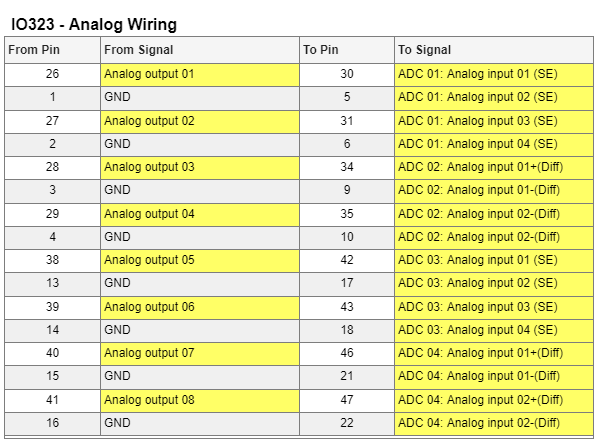

[IO323 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io323_pin_mapping) (Analog Part)

## Initialize and Open the Simulink Model

Open the Simulink model and choose your appropriate connection by commenting out the unwanted configuration block.

 
% Open Simulink model
modelName = 'sgMdl_IO323_AnalogLoopback';
open_system(modelName);
% set the model time step to 10ms
set_param(modelName, 'FixedStep', '10e-3');

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

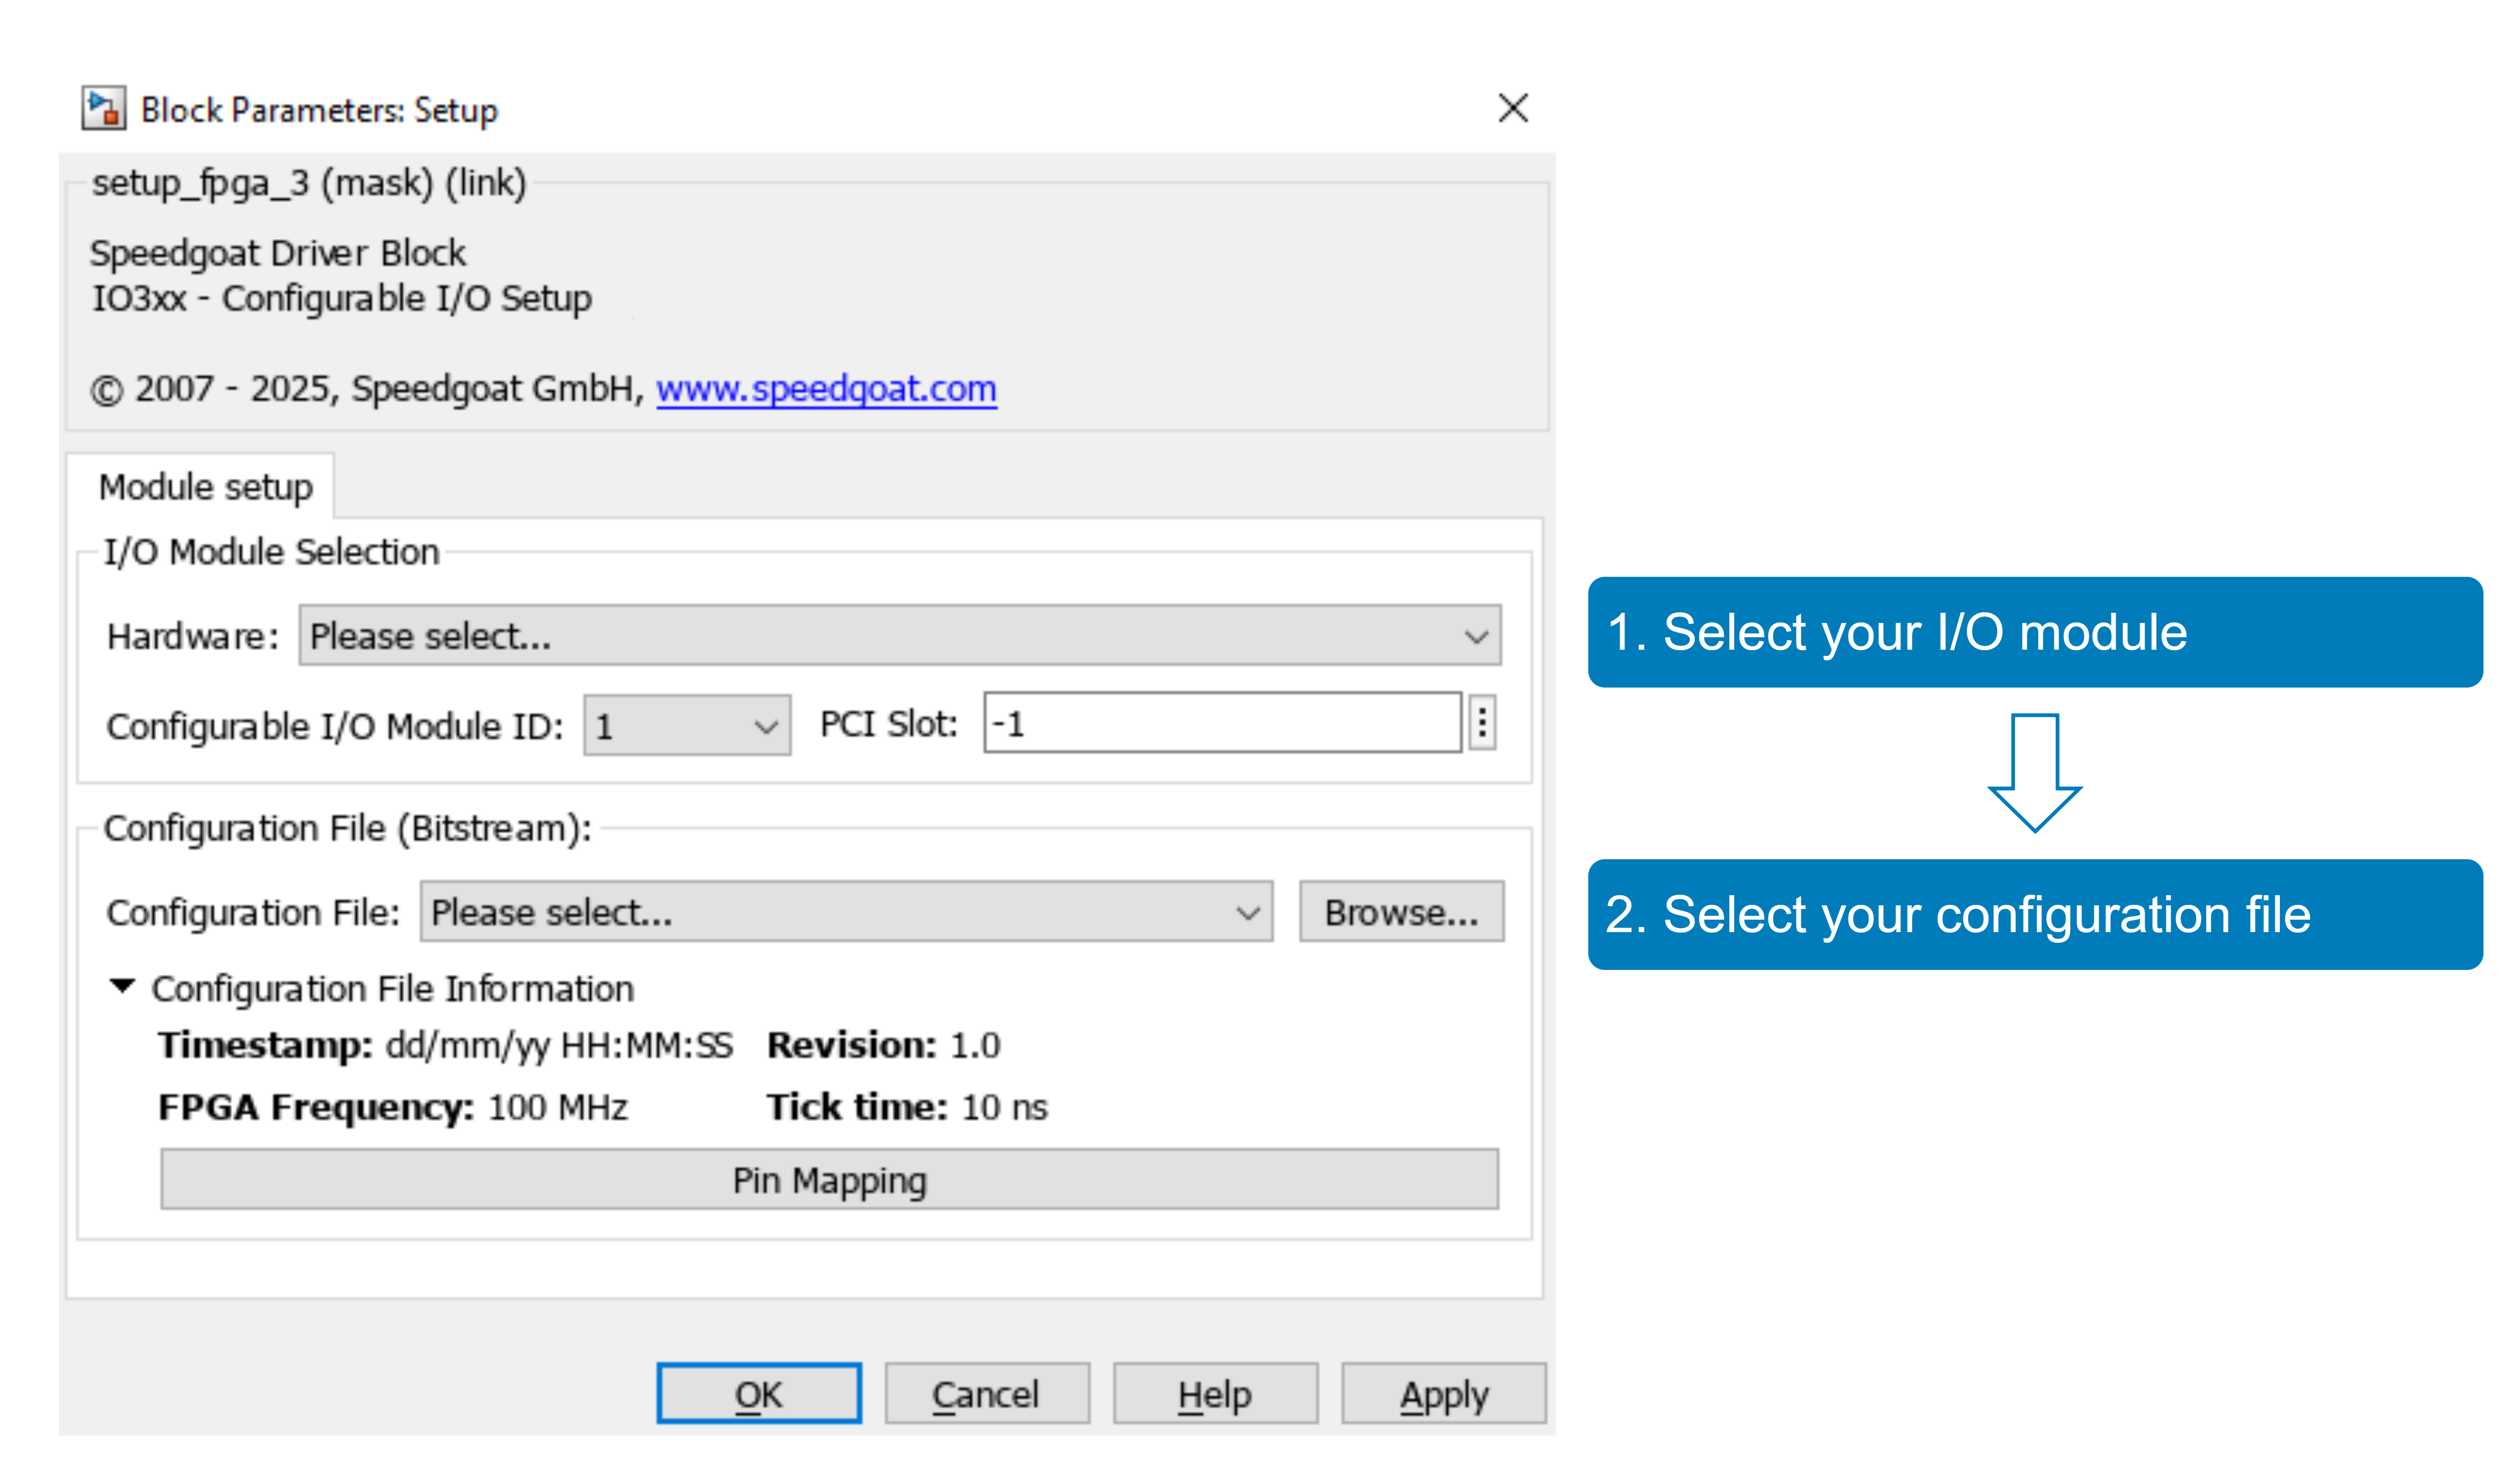

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO323 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io323) block that is needed to configure the IO323 module itself and the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1) and [IO32x Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_output_v1) blocks that are used to define the analog input and output channels of the IO323.

The model generates 8 signals that are sent to the analog outputs. Each signal is a sawtooth; while the first signal is in the range of -10 to 0, the second signal is in the range of -9 to 1, and so on. Given the loopback wiring, the same voltage values are read again on the analog inputs.

### ADC (Analog Inputs) Settings

To see the setup and parametrization of the ADC channels, open the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1) block.

 
speedgoat.model.highlight([modelName, '/IO32x Analog input'],'Open',true);  

#### Tab: ADC01

In this tab of the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1) block, you can set the channels to be measured by writing them to **Channel vector**. Note that the first channel used must always be channel 1 and only the following adjacent channels can be selected (e.g., channel 1, 2, 3, 4 is possible, but channel 2, 4 is not valid). You can select an ADC range for this group using the **Range** selection. With the **Input coupling** selection, you can select this ADC group to be either single-ended or differential. The **Trigger mode** defines if the ADC shall trigger a new measurement at model step-time (**Initiator)** or if the dedicated digital input channel shall trigger a new ADC measurement (**Target**).

The tab **ADC01** is used to configure the 8 ADC channels of this ADC group. All the other ADC channels of the other 3 ADC groups can be individually configured in the tab **ADC02**, **ADC03** and **ADC04**. Note that in this example, **ADC02** and **ADC04** are configured in **Differential** input coupling mode. 

### DAC (Analog Outputs) Settings

To see the setup and parametrization of the ADC channels, open the [IO32x Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_output_v1) block.

 
speedgoat.model.highlight([modelName, '/IO32x Analog output'],'Open',true); 

You can set the channels to generate output signals by specifying them in the **Channel vector** field. The **Trigger mode** defines if the DAC shall trigger a new output at model step-time (**Initiator)** or if the dedicated digital input channel shall trigger a new DAC measurement (**Target**). With the **Initial Values** field, you can define the behavior on the digital outputs when the real-time application is loaded, with the **Reset to Initial Value on model stop** you can choose if this should also apply when stopping the real-time application. In this example, DAC channels 1/3/5/7 reset to their initial value at stop, while the other DAC channels hold their last value.

### Analog Input (ADC) and Analog Output (DAC) Blocks

Note that the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1)[ ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_input_v1)block is set to the highest priority, to ensure the ADC conversion is done before a new DAC value is generated.

 
% Mandatory: set the Analog Input Block Priority to 1 and the Analog Output Block Priority to 2
if sg.utils.compareMatlabVersion('>', 'R2022a')
    set_param([modelName, '/IO32x Analog input'],  'priority', '1');
    set_param([modelName, '/IO32x Analog output'], 'priority', '2');
    % sorted execution order in the model
    Simulink.BlockDiagram.getExecutionOrder(modelName);
else
    warning('The priority setting is not supported in this MATLAB release, you have to enable it manually.');
end

**Note that in case your MATLAB Release is 2022a or earlier, you have to set the priorities manually in the model:**

- Right-click on the model-block **IO32x Analog input**, select **Properties...** and set the **Priority:** to 1

- Right-click on the model-block **IO32x Analog output**, select **Properties...** and set the **Priority:** to 2

- Right-click anywhere in the model and select **Other Displays -> Blocks -> Sorted Execution Order**, your model will now show the execution order of all blocks. The order execution number of the **IO32x Analog input** (higher priority) must be lower than **IO32x Analog output**

### Model Triggered Behavior

This example shall demonstrate the IO323 analog functionality using the model trigger for the ADC and the DAC unit. This means whenever the real-time application executes...

- the [IO32x Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_output_v1) block: The analog values are first transferred to the IO323 and a trigger is generated immediately afterwards so that these values are applied on the DAC outputs

- the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1)[ ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_input_v1)block: The IO323 first samples and converts the current analog inputs before they are provided to the real-time application.

As described above, the trigger setting can be selected in the [IO32x Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_output_v1) and the [IO32x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_input_v1) drivers (the parameter **Trigger mode** must be set to **Initiator**):

 
% set the Trigger Source for ADC and DAC to model
set_param([modelName, '/IO32x Analog output'], 'trigger', 'Initiator');
set_param([modelName, '/IO32x Analog input'], 'ADC1_trigger', 'Initiator');
set_param([modelName, '/IO32x Analog input'], 'ADC2_trigger', 'Initiator');
set_param([modelName, '/IO32x Analog input'], 'ADC3_trigger', 'Initiator');
set_param([modelName, '/IO32x Analog input'], 'ADC4_trigger', 'Initiator');

In this case, with all the triggers set to Initiator, the trigger signals will generate a short pulse whenever the DACs or the ADCs are triggered. To locate these trigger signals, you can open the pin mapping by clicking the **Pin Mapping** button in the [IO323 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io323) block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Define and set stop-time
stoptime = 4.5; % Simulation length [s]

tg.setStopTime(stoptime);

% Start the real-time application
tg.start;
pause(stoptime+1);

## Show and Analyze the Signals

To show the measured signals, either run the following code section or click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink model.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);         % layout with two plots

% get signals by name (signal label in Simulink)
ADC_Signal_1 = SDIRun.getSignalsByName('ADC in.CH1_ADC_01_Single');
ADC_Signal_2 = SDIRun.getSignalsByName('ADC in.CH3_ADC_01_Single');
ADC_Signal_3 = SDIRun.getSignalsByName('ADC in.CH9_ADC_02_Diff');
ADC_Signal_4 = SDIRun.getSignalsByName('ADC in.CH11_ADC_02_Diff');
ADC_Signal_5 = SDIRun.getSignalsByName('ADC in.CH17_ADC_03_Single');
ADC_Signal_6 = SDIRun.getSignalsByName('ADC in.CH19_ADC_03_Single');
ADC_Signal_7 = SDIRun.getSignalsByName('ADC in.CH25_ADC_04_Diff');
ADC_Signal_8 = SDIRun.getSignalsByName('ADC in.CH27_ADC_04_Diff');
DAC_Signal = SDIRun.getSignalsByName('DAC out');

% expand signals 
expand(ADC_Signal);
expand(DAC_Signal);

% assign DAC signals to subplot 1
plotOnSubPlot(DAC_Signal.Children(1),1,1,true);
plotOnSubPlot(DAC_Signal.Children(2),1,1,true);
plotOnSubPlot(DAC_Signal.Children(3),1,1,true);
plotOnSubPlot(DAC_Signal.Children(4),1,1,true);
plotOnSubPlot(DAC_Signal.Children(5),1,1,true);
plotOnSubPlot(DAC_Signal.Children(6),1,1,true);
plotOnSubPlot(DAC_Signal.Children(7),1,1,true);
plotOnSubPlot(DAC_Signal.Children(8),1,1,true);

% assign ADC signals to subplot 1
plotOnSubPlot(ADC_Signal_1,2,1,true);
plotOnSubPlot(ADC_Signal_2,2,1,true);
plotOnSubPlot(ADC_Signal_3,2,1,true);
plotOnSubPlot(ADC_Signal_4,2,1,true);
plotOnSubPlot(ADC_Signal_5,2,1,true);
plotOnSubPlot(ADC_Signal_6,2,1,true);
plotOnSubPlot(ADC_Signal_7,2,1,true);
plotOnSubPlot(ADC_Signal_8,2,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",-0.05,"tMax",4.55);   % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-10.5,"yMax",7.5);    % set y-zoom of channel 1
Simulink.sdi.setSubplotLimits(2,1,"yMin",-10.5,"yMax",7.5);    % set y-zoom of other channels

### Check the Results

The SDI view shows you the generated DAC output values and the measured ADC input values.

Each signal is a sawtooth with a difference of 10 V. Channel 1 starts at -10 V, and Channel 2 starts at -9 V, and so on.

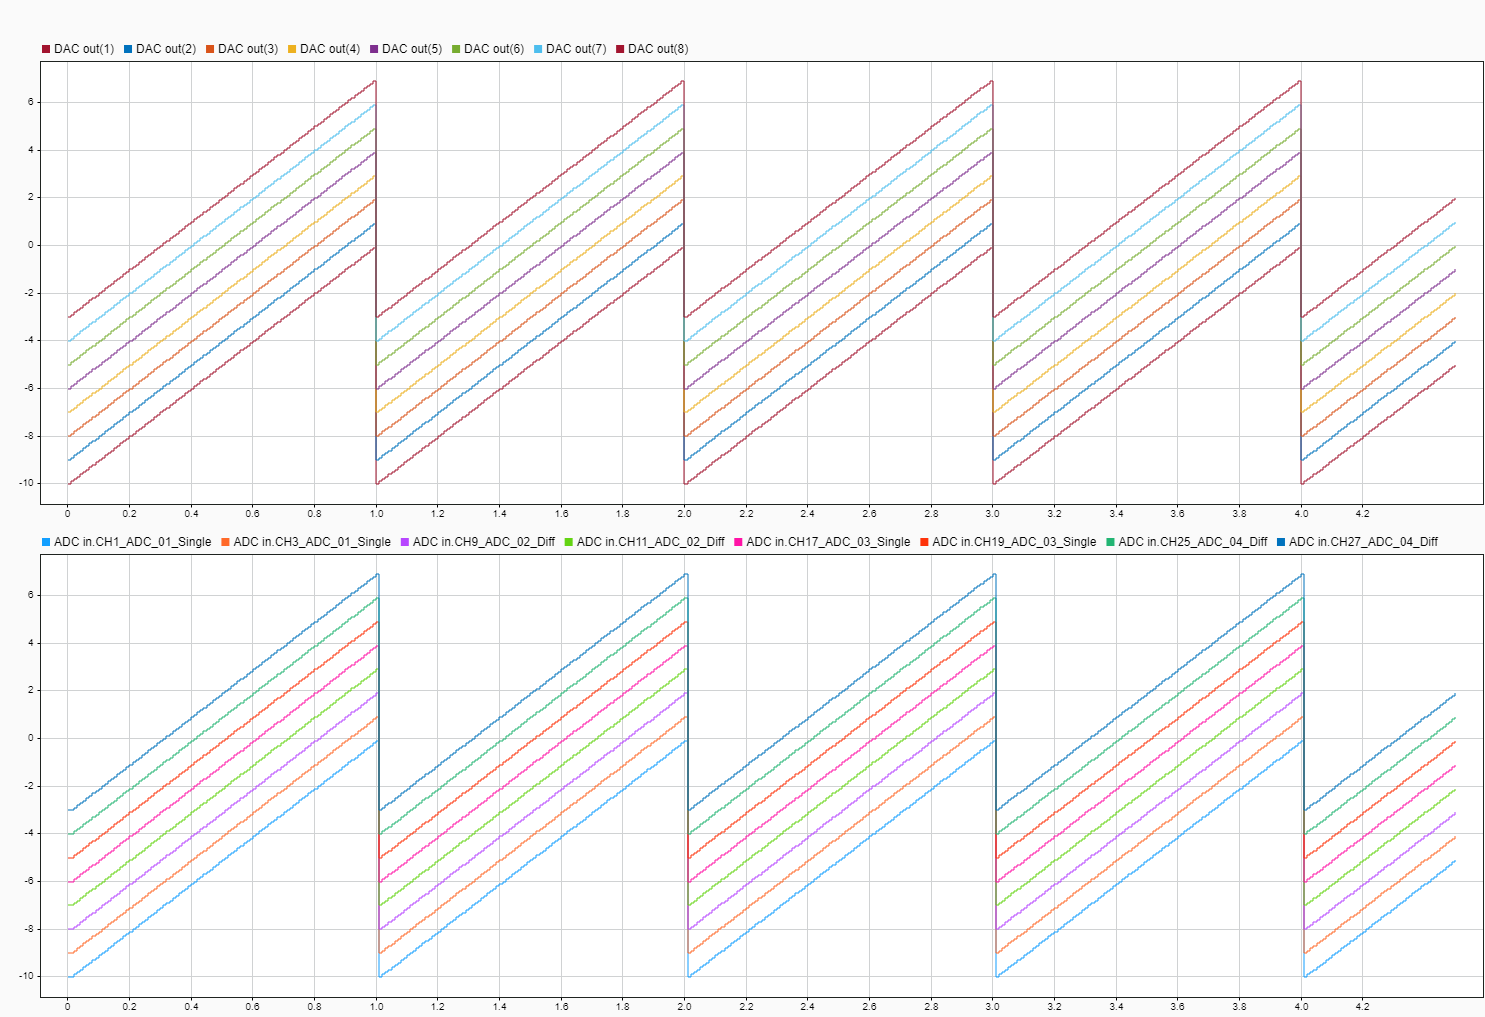

The ADC in values match the DAC out values.

Note that there is one sample step delay between the ADC out values and the DAC in values (this can be better observed by time-zooming on a point where the sawtooth finished):

 
% Zoom in around T = 1s
Simulink.sdi.setSubplotLimits(1,1,"tMin",0.8,"tMax",1.2);   % set time span

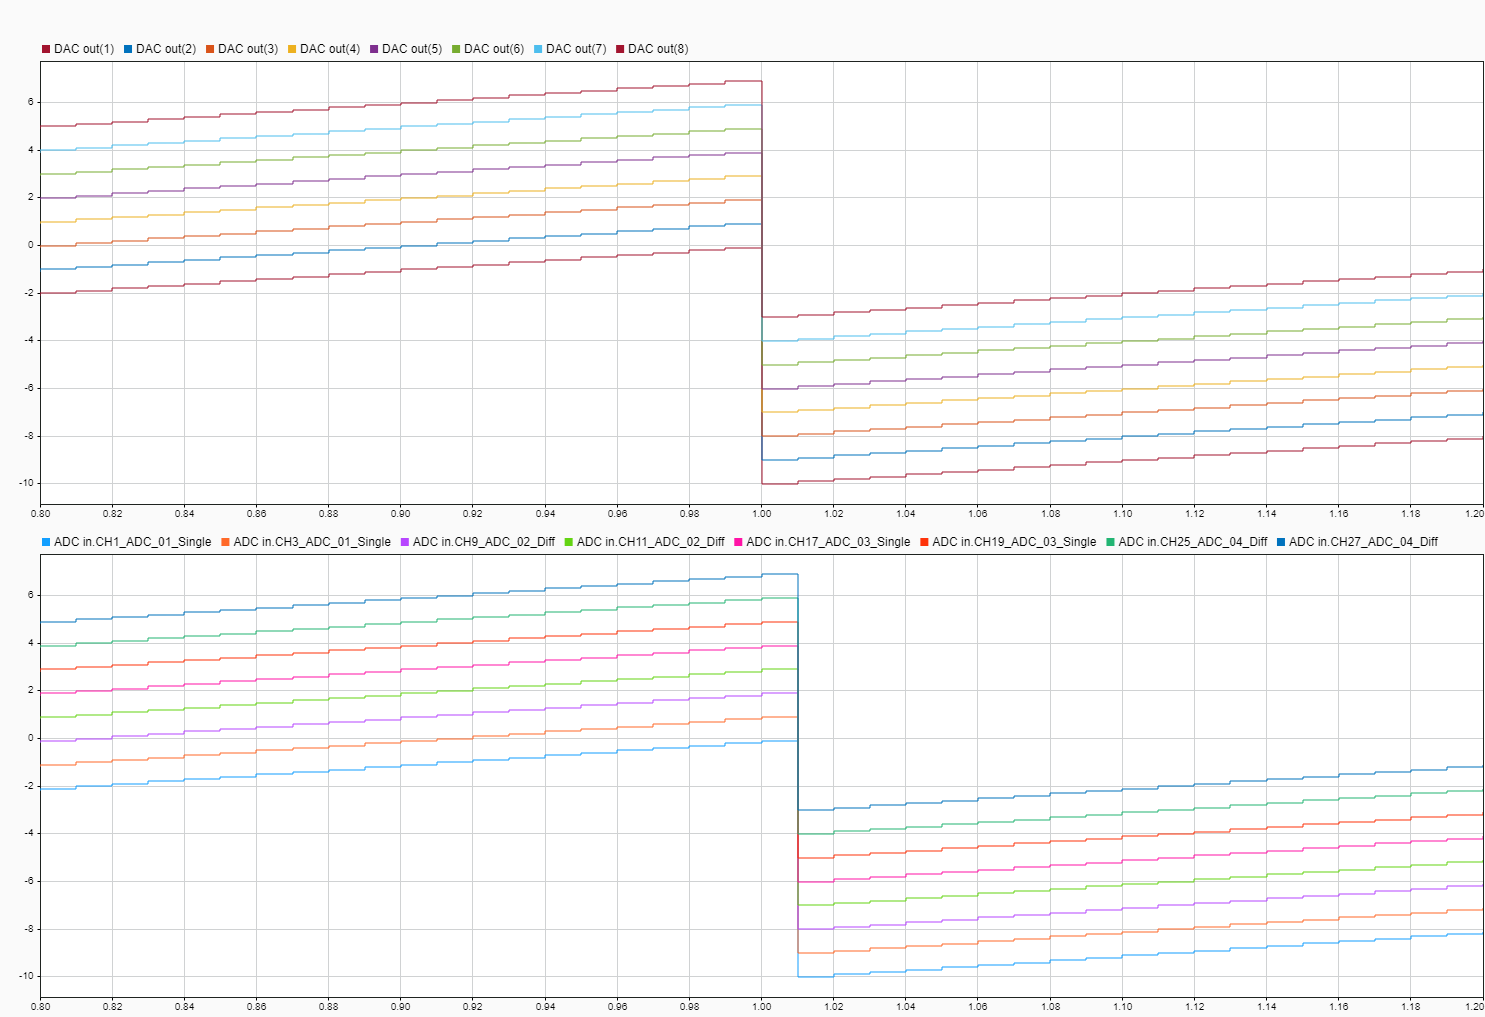

#### Measuring the DAC Values after Model Stop

As described, the signals for the DAC are "saw teeth" that restart every second. As you can see, the stop-time of this example is set to 4.5 s, which is the "middle" of the sawtooth. This can also be seen by the above scope signals at the end.

Remember that we set **Reset to Initial Value** on DAC channels 1/3/5/7.

Therefore, you can optionally measure the DAC outputs at the end of the simulation using a standard multimeter and manually measure the DAC signals. Regarding this example and the settings in the [IO32x Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_analog_io32x_output_v1) block, you should measure the following voltages at the DAC outputs after the model has stopped:

- DAC1: -10 V (**Reset to Initial Value** is set, **Initial Value** is set to -10 V)

- DAC2:  -4 V (**Reset to Initial Value** is NOT set), -4 V is the last DAC Value at model stop

- DAC3:  -8 V (**Reset to Initial Value** is set, **Initial Value **is set to -8 V)

- DAC4:  -2 V (**Reset to Initial Value** is NOT set), -2 V is the last DAC Value at model stop

- DAC5:  -6 V (**Reset to Initial Value** is set, **Initial Value** is set to -6 V)

- DAC6:   0 V (**Reset to Initial Value** is NOT set), 0 V is the last DAC Value at model stop

- DAC7:  -4 V (**Reset to Initial Value** is set, **Initial Value** is set to -4 V)

- DAC8:   2 V (**Reset to Initial Value** is NOT set), 2 V is the last DAC Value at model stop

## Additional References

- [IO323 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io323)

- [Analog IO32x](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io32x)